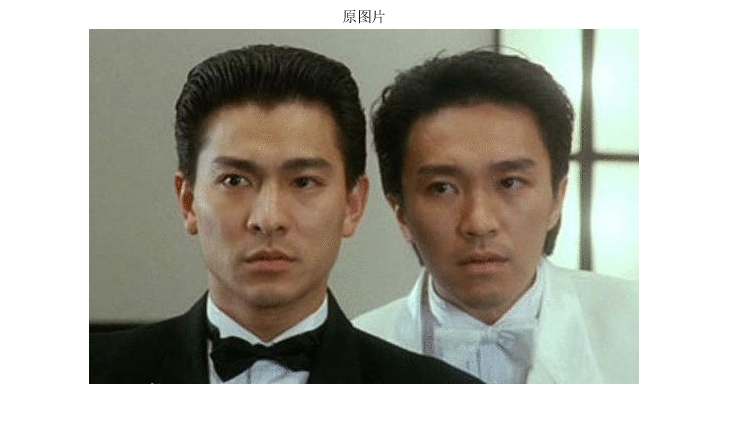

clc;
clear;
I=imread("10-刘德华.jpg");
I=im2double(I);
figure
imshow(I);
title("原图片");

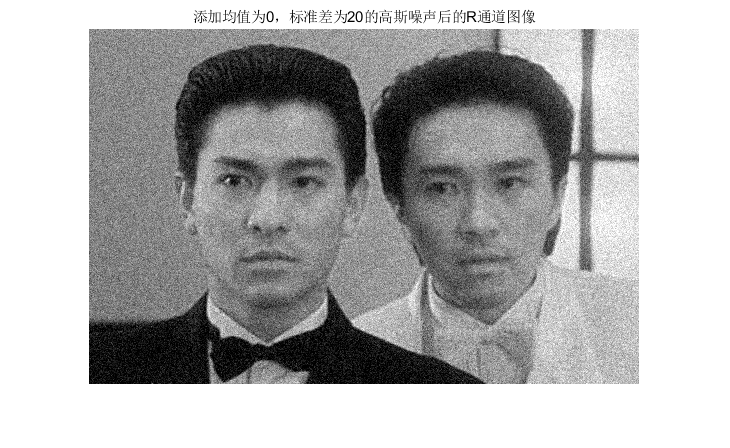

%取出RGB三通道
I_R=I(:,:,1);
I_G=I(:,:,2);
I_B=I(:,:,3);
[row,col,~]=size(I);
%对R通道添加均值为0，标准差为20的高斯噪声
noise_gauss=0+20*randn(row,col);
I_R_noise=255*I_R+noise_gauss;
I_R_noise=uint8(I_R_noise);
%绘图
figure
imshow(uint8(I_R_noise));
title("添加均值为0，标准差为20的高斯噪声后的R通道图像");

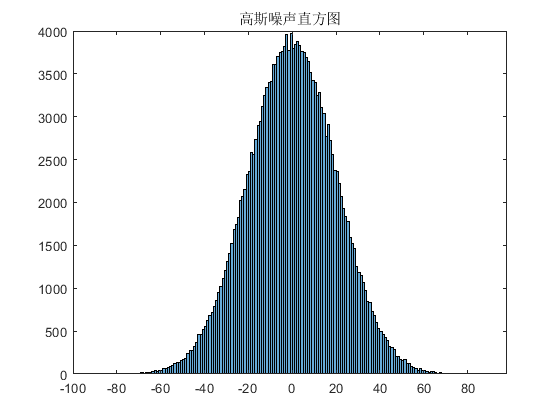

%绘制噪声直方图
figure
histogram(noise_gauss);
title("高斯噪声直方图");

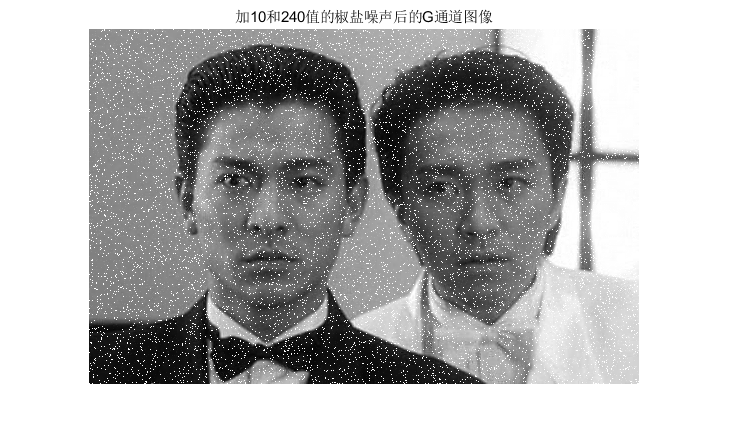

%对G通道添加10和240值的椒盐噪声，椒、盐概率均为0.05
p=0.05;
noise_salt=10*(rand(row,col)<p); %生成盐噪声
noise_paper=240*(rand(row,col)<p); %生成椒噪声
noise=noise_salt+noise_paper;
I_G_noise=255*I_G+noise; %添加到图像中
I_G_noise=uint8(I_G_noise);
%绘图
figure
imshow(uint8(I_G_noise));
title("加10和240值的椒盐噪声后的G通道图像");

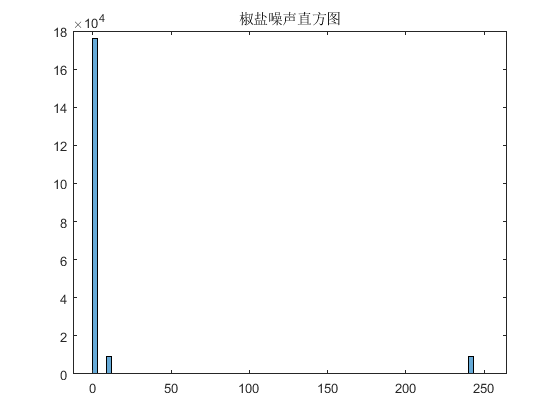

%绘制噪声直方图
figure
histogram(noise);
title("椒盐噪声直方图");

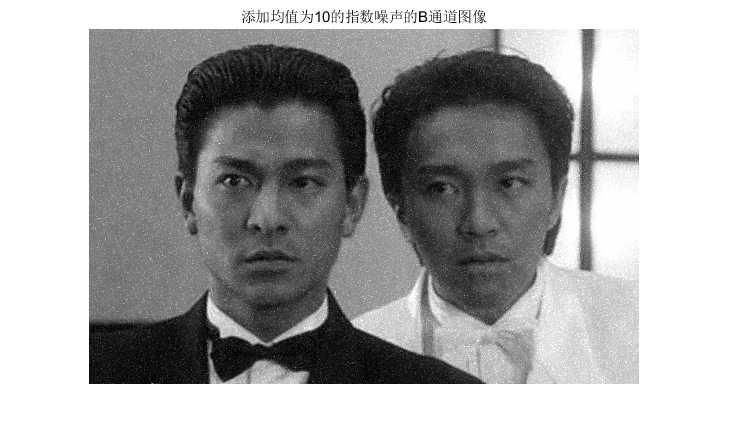

%对B通道添加均值为10的指数噪声
mean=10;
noise_exp=exprnd(mean,row,col);
I_B_noise=255*I_B+noise_exp; %添加到图像中
I_B_noise=uint8(I_B_noise);
%绘图
figure
imshow(I_B_noise);
title("添加均值为10的指数噪声的B通道图像");

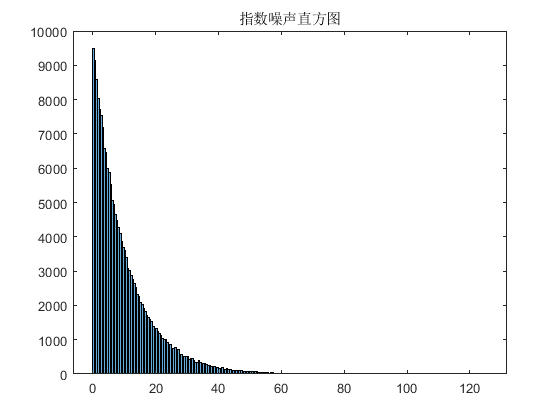

%绘制噪声直方图
figure
histogram(noise_exp);
title("指数噪声直方图");

%储存
imwrite(I_R_noise,'添加高斯噪声的R通道图像.jpg',"jpg");
imwrite(I_G_noise,'添加椒盐噪声的G通道图像.jpg',"jpg");
imwrite(I_B_noise,'添加指数噪声的B通道图像.jpg',"jpg");